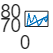

% Yash Maisuria Code for Plotting, Salting, and Smoothing Data in MATLAB

% Step 1: Import data from CSV file
data = readmatrix('C:/Users/yashm/OneDrive/Documents/SU - CSCI-3327-001 - PROBABILITY AND APPLIED STATS/PROGRAMMING/data.csv');

% Step 2: Extract x and y from the imported data
x = data(:, 1);
y = data(:, 2);

% Step 3: Plot the original data
figure;
plot(x, y);

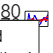


% Step 4: Salt the data
salted_y = y + 0.1 * randn(size(y));

% Step 5: Smooth the data
smoothed_y = movmean(salted_y, 5);

% Step 6: Plot the salted and smoothed data
figure;
plot(x, salted_y, 'b');
hold on;
plot(x, smoothed_y, 'r');
legend('Salted', 'Smoothed');